Definicja prostego modelu epidemii SI (dla uproszczenia zrobiono normalizację $N=1$):


$$\left\lbrack \begin{array}{c}
\dot{S} \\
\dot{I} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-\beta \mathrm{SI}+\gamma I\\
\beta \mathrm{SI}-\gamma I
\end{array}\right\rbrack$$


syms S I real
assume(S>=0)
assume(I>=0)
syms gamma beta real positive
assume(beta>gamma)
f = [-beta*S*I+gamma*I; beta*S*I-gamma*S];

Szukamy punktów równowagi:

xe = solve(f == [0;0], {I,S}, ReturnConditions=true)

xe = struct with fields:
             I: [4×1 sym]
             S: [4×1 sym]
    parameters: x
    conditions: [4×1 sym]


Definicja ukladu zredukowanego do jednego wymiaru:


$$\dot{I} = I(\beta(N-I)-\gamma)$$


f1d = I*(beta*(1-I)-gamma);

Wyznaczenie punktów równowagi:

xe1d = solve(f1d == 0, {I}, ReturnConditions=true)

xe1d = struct with fields:
             I: [2×1 sym]
    parameters: [1×0 sym]
    conditions: [2×1 sym]


Wyznaczenie linearyzacji i określenie stbilności na podstawie pośredniego kryterium Lapunowa:

equilibriums_number = length(xe1d.I);
for index = 1:equilibriums_number
    % Zamiana zmiennych
    syms z real
    f_z = subs(f1d, {I}, {z+xe1d.I(index)});
    % Wyznaczenie jakobianu
    A_z = jacobian(f_z, z);
    % Wyznaczenie r(x)/||x||
    r_ratio_z = simplify((f_z - A_z*z) / norm(z));
    % Sprawdzenie granicy
    L = limit(r_ratio_z, z, 0);
    if double(norm(L)) ~= 0
        disp("Punkt równowagi " + index + " nie może być zweryfikowany za pomocą kryterium pośredniego.");
        continue;
    end
    % Wyznaczenie numrycznej wartości jakobianu
    A = subs(A_z, {z}, {0});
    bg = solve(A < 0, [gamma, beta]);
    % Sprawdzenie stabilności
    if isempty(bg.gamma) & isempty(bg.beta)
        disp("Punkt równowagi " + index + " jest niestabilny");
    else
        disp("Punkt równowagi " + index + " jest stabilny");
    end
end

Punkt równowagi 1 jest niestabilny


Punkt równowagi 2 jest stabilny


Propozycja funkcji Lapunowa:


$$V\left(I\right)=\frac{1}{2}{\left(I-I_e \right)}^2$$


V1d = 0.5*(I-((beta - gamma)/beta))^2;

Wyznaczenie pochodnej po trajektoriach systemu:

V1ddot = simplify(gradient(V1d, I)' * f1d);
fprintf("Pochodna po trajektoriach systemu: %s", string(V1ddot));

Pochodna po trajektoriach systemu: -(I*(gamma - beta + I*beta)^2)/beta

Sprawdzenie gdzie pochodna funkcji Lapunowa się zeruje:

xe = solve(V1ddot == 0, I) % <- zeruje się tylk ow punktach równowagi

$$xe = \left(\begin{array}{c} 0\\ \frac{\beta -\gamma }{\beta }\\ \frac{\beta -\gamma }{\beta } \end{array}\right)$$

Wyrysowanie fukcji Lapunowa i je pochodnej:

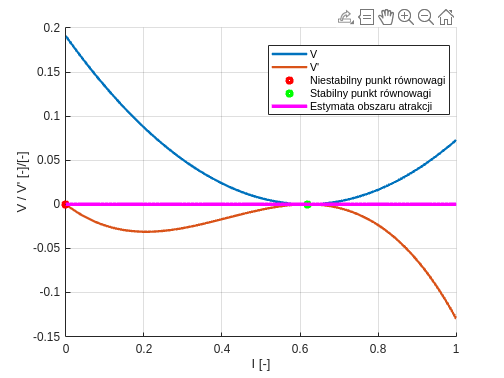

gamma = 0.34;
beta = 0.89;
if gamma > beta
    error("Niespełnione założenie beta > gamma");
end
 
I = 0:0.01:1;
Ie = (beta-gamma)/beta; 
Vnum = 0.5*(I-Ie).^2;
Vdotnum = -(I.*(gamma - beta + I*beta).^2)/beta;

figure();
grid on;
hold on;
xlabel("I [-]");
ylabel("V / V' [-]/[-]");
legend("show", "Location", "best");

plot(I, Vnum, "LineWidth", 2, "DisplayName", "V");
plot(I, Vdotnum, "LineWidth", 2, "DisplayName", "V'");
plot(0, 0, "ro", "LineWidth", 3, "MarkerSize", 4, "DisplayName", "Niestabilny punkt równowagi");
plot(Ie, 0, "go", "LineWidth", 3, "MarkerSize", 4, "DisplayName", "Stabilny punkt równowagi");

% Wyrysowanie obszaru przyciągania
l = 0.22;
index = Vnum < l;
Ia = I(index);
plot(Ia, zeros(size(Ia)), "m", "LineWidth", 3, "DisplayName", "Estymata obszaru atrakcji");

Wyrysowanie portretu fazowego dla układu wyjściowego 2D:

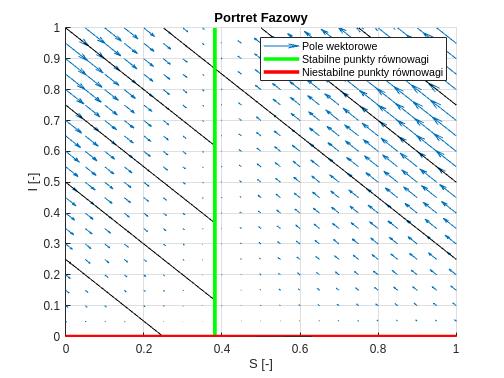

[S, I] = meshgrid(0:0.05:1);
dS = -beta.*S.*I + gamma.*I;
dI = beta.*S.*I - gamma.*I;

figure();
grid on;
hold on;
xlabel("S [-]");
ylabel("I [-]");
title("Portret Fazowy");
xlim([0, 1]);
ylim([0, 1]);
legend("show");

quiver(S, I, dS, dI, 2, "DisplayName", "Pole wektorowe");

X0 = {[0;1], [0.25;1], [0.5;1], [0.75;1], [1;1], ...
      [0;0], [0.25;0], [0.5;0], [0.75;0], [1;0], ...
      [0;0], [0;0.25], [0;0.5], [0;0.75], [0;1], ...
      [1;0], [1;0.25], [1;0.5], [1;0.75], [1;1]};

f_num = @(t, x)[-beta*x(1)*x(2)+gamma*x(2);beta*x(1)*x(2)-gamma*x(2)];

for index = 1:length(X0)
    x0 = X0{index};
    [~, y] = ode45(f_num,0:0.1:100, x0);
    plot(y(:, 1), y(:, 2), "k", "HandleVisibility", "off");
end

% Wyrysowanie punktów równowagi
plot([1-Ie, 1-Ie], [0, 1], "g", "LineWidth", 3, "DisplayName", "Stabilne punkty równowagi");
plot([0, 1], [0, 0], "r", "LineWidth", 3, "DisplayName", "Niestabilne punkty równowagi");